# Derivation of DFT

## given function is f(x) = 5 + 2 cos(2 pi x - pi/2 ) + 3 cos(4 pi x)

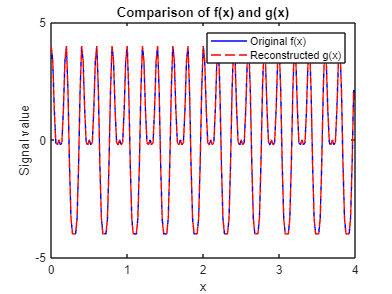

clear
clc
sample_number = 200;
sample_rate = 50;               
period=sample_number /sample_rate;
deltax = 1/sample_rate;
x=0:deltax:period-deltax;
f = 3* cos(10* pi* x ) + 2* sin(5* pi* x)+ cos(20* pi* x );

W_n = exp(2*pi/sample_number*i);

f_head = zeros(1, sample_number);
for k=0:sample_number-1;
    sum_term=0;
    for n=1:sample_number;
        
        sum_term= sum_term + f(n)*W_n^(-k*(n-1));
    end
    f_head(k+1)=sum_term;
  
end

% amplitude of any given function 
A=zeros(1,sample_number);
for k=1:sample_number
    A(k) = norm(f_head(k))/sample_number;
end

% phase shift of any given function
theta = zeros(1, sample_number);
for k=1:sample_number
    a=f_head(k);
    theta(k) =atan2(imag(a),real(a));    % Faz kaymasını hesapla
    
end

%Frequency of any given function
W = zeros(1, sample_number);
for k=0:sample_number-1
    W(k+1) = 2*pi*k/period;
end

%new function g(x) = sum [ A(k) * cos(Wk x + theta(k)) ] | k from 0 to N-1
g = zeros(size(x));
for k=1:sample_number
    g=A(k)*cos(W(k)*x+theta(k))+g;
end

figure
plot(x, f, 'b')  % Gerçek fonksiyon
hold on
plot(x, g, 'r--')  % Fourier serisinden türetilen fonksiyon
legend('Original f(x)', 'Reconstructed g(x)')
title('Comparison of f(x) and g(x)')
xlabel('x')
ylabel('Signal value')